## **Problem 5**

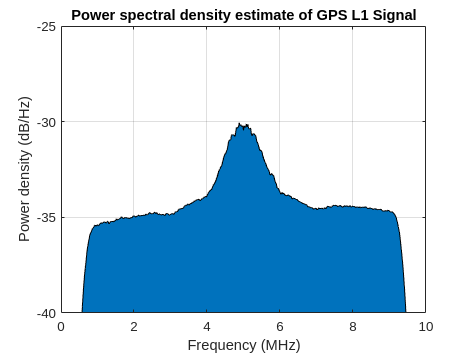

clear all; clc; close all;
%----- Setup
Tfull = 0.5;     % Time interval of data to load
% fsampIQ = 5.0e6; % IQ sampling frequency (Hz)
fsampIQ = 10.0e6; % IQ sampling frequency (Hz)
N = floor(fsampIQ*Tfull);
nfft = 2^9;      % Size of FFT used in power spectrum estimation
%----- Load data
% fid = fopen('niData01head_5MHz.bin','r','l');
fid = fopen('niData03head_10MHz.bin','r','l');
Y = fread(fid, [2,N], 'int16')';
Y = Y(:,1) + j*Y(:,2);
fclose(fid);

% Power Spectral Density(PSD) of the baseband signal representation
[Syy, fVec] = pwelch(Y,hann(nfft),[],nfft,fsampIQ);
plotPSD(Syy, fVec, nfft, fsampIQ, -40, -25);

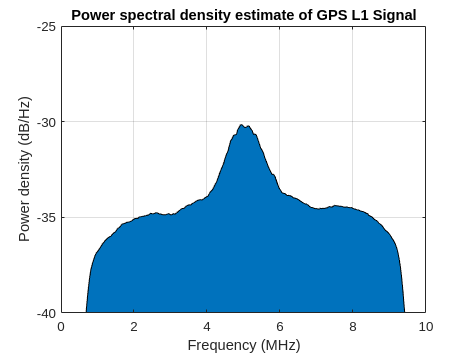


% Convert signal to its bandpass representation and compute PSD
fIF = 5e6;
Tl  = 1/fsampIQ;
xVec = iq2if(real(Y),imag(Y),Tl,fIF);
[Syy_if, fVec_if] = pwelch(xVec,hann(nfft),[],nfft,2*fsampIQ);
plotPSD(Syy_if, fVec_if, nfft, 2*fsampIQ, -40, -25);

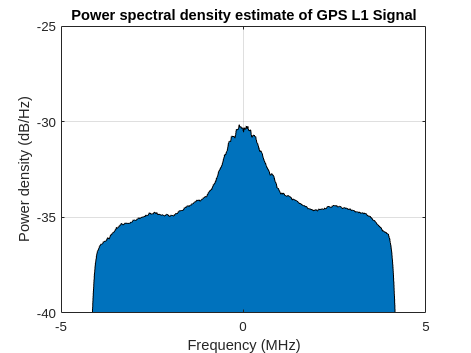


% Convert signal to its baseband representation and compute PSD
T = Tl/2;
[IVec,QVec] = if2iq(xVec,T,fIF);
Y_reconstructed = IVec + j*QVec;
[Syy_IQ, fVec_IQ] = pwelch(Y_reconstructed,hann(nfft),[],nfft,fsampIQ);
plotPSD(Syy_IQ, fVec_IQ, nfft, fsampIQ, -40, -25);

## **Problem 8**

clc; clear all; close all;
format long g

% Solution to the Problem
fDk = [...
    1121.6 ...
   -1551.17 ...
   -1222.22 ...
   -2711.30 ...
   -2652.97 ...
    3103.75 ...
    2049.57 ...
    2186.67 ...
    2459.39 ...
   -1424.31 ...
];

rho = [ ...
    20985472.06 ...
    19972502.03 ...
    18551086.07 ...
    19765301.28 ...
    20277962.34 ...
    21700953.46 ...
    23269270.58 ...
    22529297.11 ...
    19915944.89 ...
    19728164.68 ...
];

SV_present = [1 2 5 10 12 15 21 24 29 30];

%----- Setup
Tfull = 0.5;     % Time interval of data to load
fsampIQ = 5.0e6; % IQ sampling frequency (Hz)
TsampIQ = 1/fsampIQ;
N = floor(fsampIQ*Tfull);
nfft = 2^9;      % Size of FFT used in power spectrum estimation
%----- Load data
fid = fopen('niData01head_5MHz.bin','r','l');
Y = fread(fid, [2,N], 'int16')';
fclose(fid);

tau = TsampIQ*(0:1:N-1)'; % sampling time (in RX time base)
xVec = Y(:,1) + j*Y(:,2); % complex baseband representation
fStep = 10; % Hz
nStep = 1;  % Ts

for TXID = 1:37
    [fDk_hat(TXID), tsk_hat(TXID), detected(TXID)] = acquireGPS(tau, xVec, TsampIQ, 3, ...
                                                        fStep, nStep, TXID, 'FFT');
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).



if SV_present == find(detected == 1)
    if abs(fDk_hat(SV_present) - fDk) < 5*fStep
        display('Succesful detection')
    else
        display('Detection worked but the doppler frequencies are off')
    end

    tsk_h = tsk_hat(SV_present);
    for i = 1:length(rho)-1
        tsk(i) = mod((rho(1) - rho(i+1))/physconst('LightSpeed'), 1e-3) * 1e6;
        tsk_check(i) = mod(tsk_h(1) - tsk_h(i+1), 1e3); 
    end
    
    fDk_hat(SV_present)'
    [round(tsk',2) round(tsk_check',2)]
else
    display('Detection failed!')
end

Arrays have incompatible sizes for this operation.

Related documentation

## **Problem 8 (Exam)**

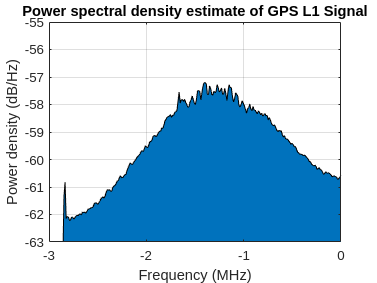

clc; clear all; close all; format long g;
%----- Setup
Tfull = 0.5;     % Time interval of data to load
fs = (40/7)*1e6; % IQ sampling frequency (Hz)
Ts = 1/fs;
N = floor(fs*Tfull/16)*16;
nfft = 2^9;      % Size of FFT used in power spectrum estimation
%----- Load data
fileName = 'dataout_raw_trimmed_158.bin';
fid = fopen(fileName,'r','l');
[yhist,count] = binloadSamples(fid,N,'dual');
yhist = yhist(:,1);
fclose(fid);

%----- Compute power spectrum estimate
[Syy,fVec] = pwelch(yhist,hann(nfft),[],nfft, fs);
plotPSD(Syy, fVec, nfft, fs, -63, -55);

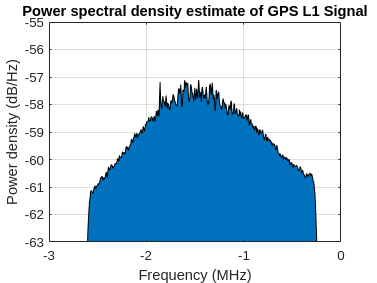


% Convert signal to its baseband representation and compute PSD
fIF = 1610476.187;
[IVec,QVec] = if2iq(yhist, Ts, fIF);
xVec = IVec + j*QVec;
[Syy_IQ, fVec_IQ] = pwelch(xVec,hann(nfft),[],nfft, fs/2);
plotPSD(Syy_IQ, fVec_IQ, nfft, fs, -63, -55);

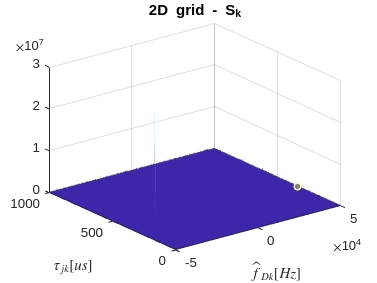


tau = (Ts*2)*(0:1:N-1)'; % sampling time (in RX time base)

fStep = 100; % Hz
nStep = 1;  % Ts
for TXID = 18:18
    [fDk_hat(TXID), tsk_hat(TXID), detected(TXID)] = acquireGPS(tau, xVec, Ts*2, 5, ...
                                                        fStep, nStep, TXID, 'FFT');
end